# Scatter plots

Read data

load('cardata.mat');

Scatter plot of MPG vs Horsepower

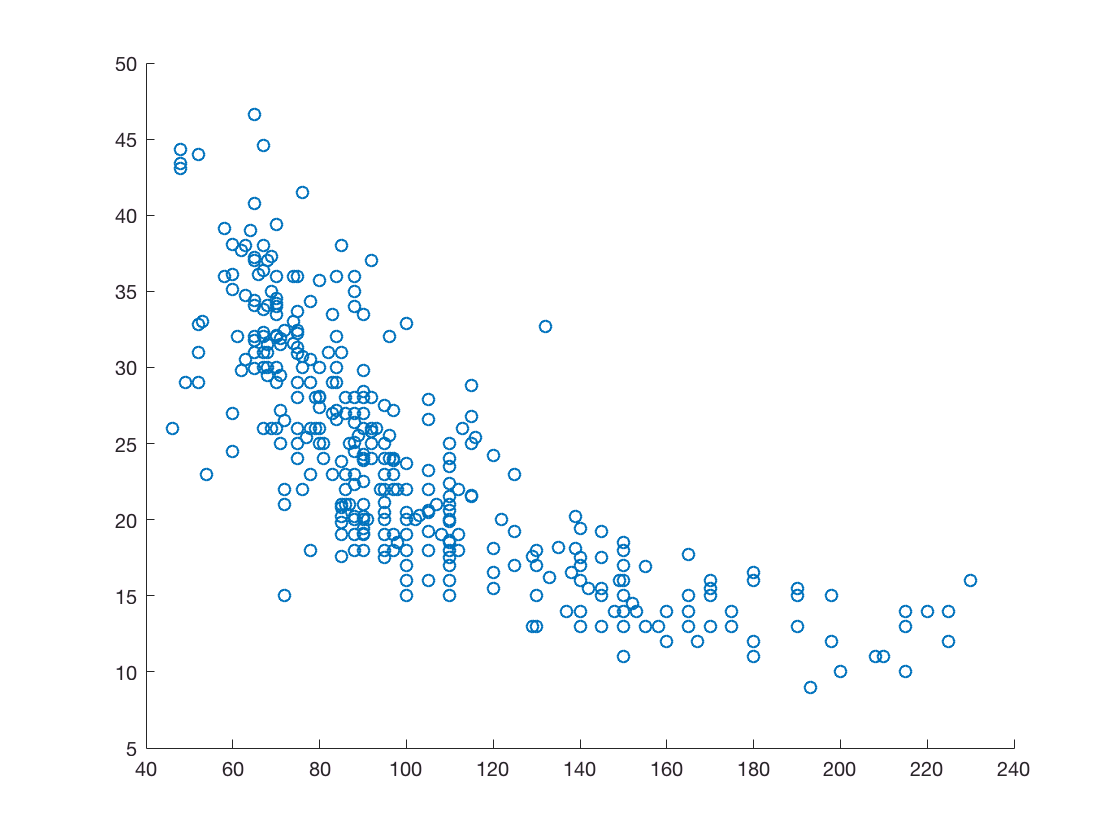

sc = scatter(Horsepower, MPG);

Add Accelaration values to marker size

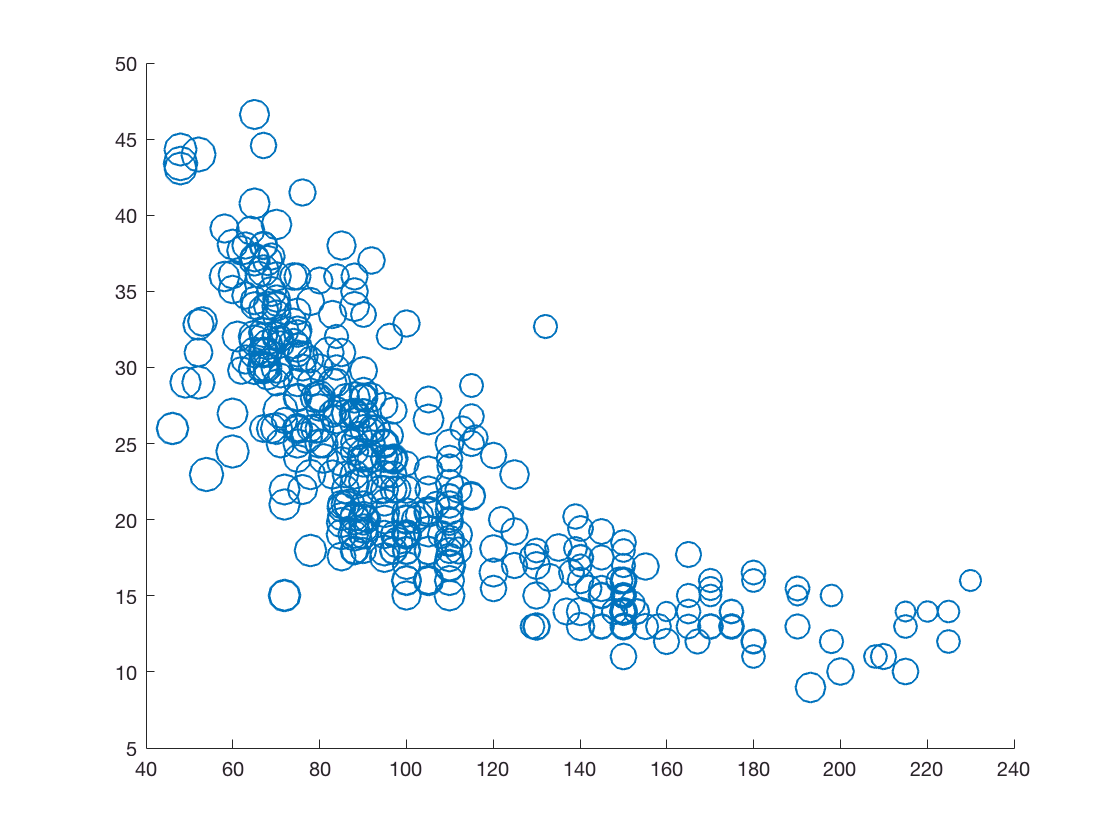

sc = scatter(Horsepower, MPG, Acceleration*12);

Add Weight as a colormap

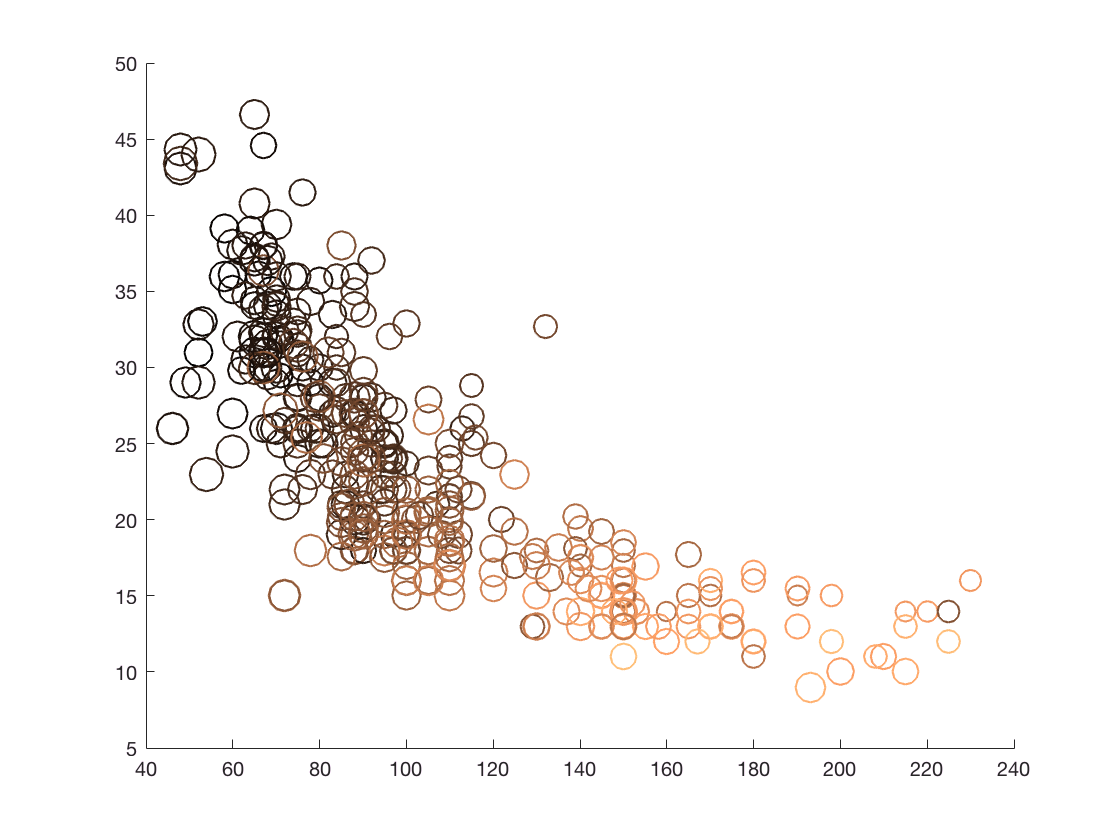

sc = scatter(Horsepower, MPG, Acceleration*12, Weight);
colormap('copper');

Modify marker properties

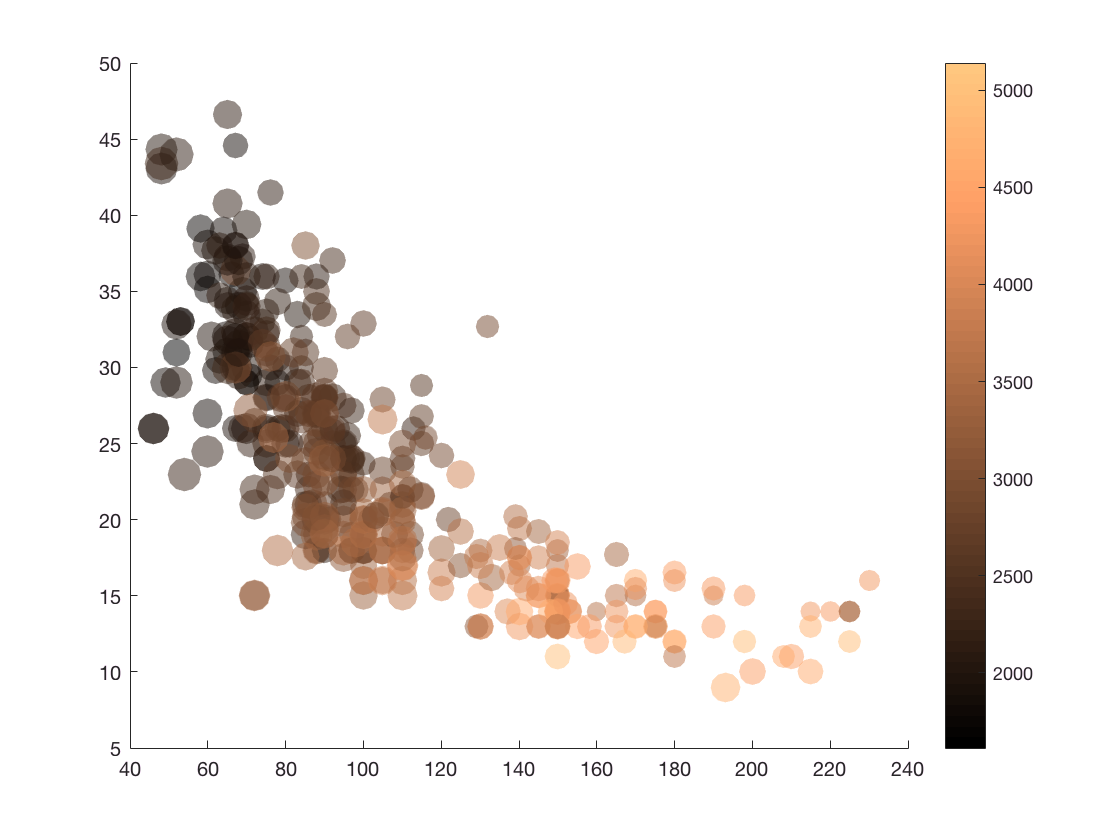

sc.MarkerFaceColor = 'flat';
sc.MarkerEdgeColor = 'none';
sc.MarkerFaceAlpha = 0.5;
cbar = colorbar();

Modify axis properties, add axis labels/titles, and change fontsize

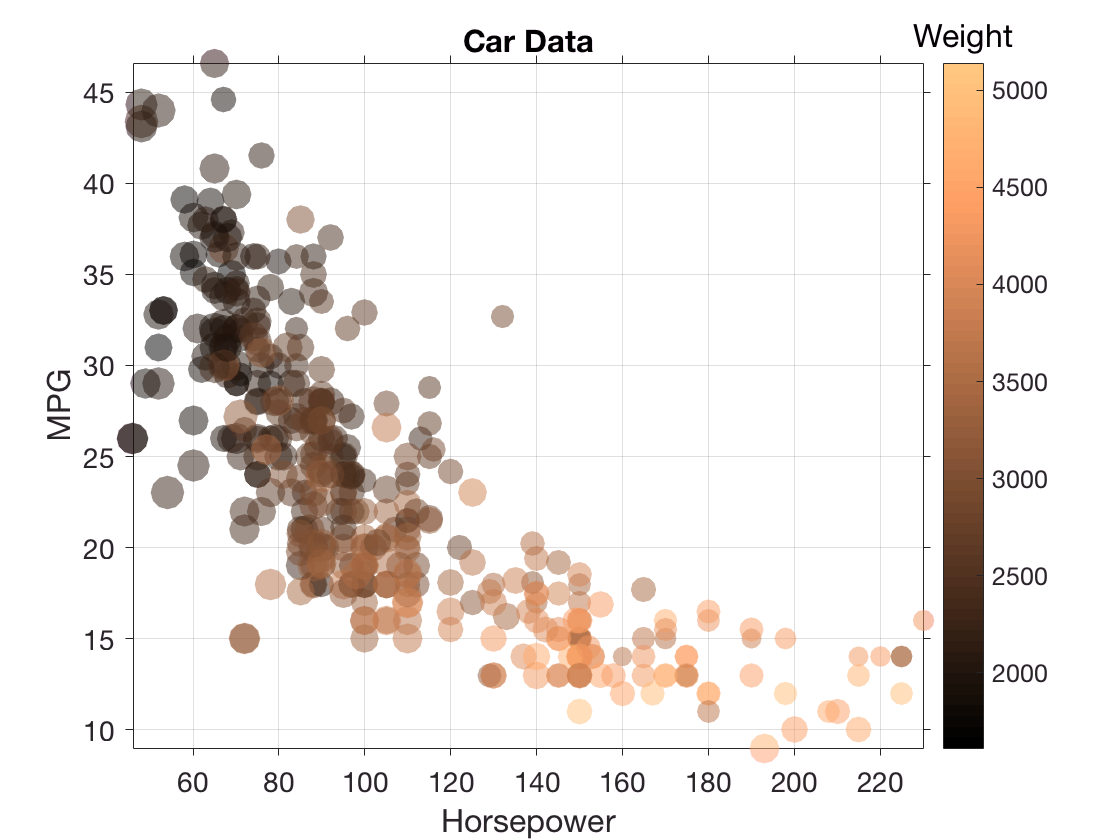

ax = gca;
ax.Box = 'on';
ax.FontSize = 14;
ax.TickDir = 'out';
xlabel('Horsepower', 'Fontsize', 16);
ylabel('MPG', 'Fontsize', 16);
title(cbar, 'Weight', 'Fontsize', 16);
title(ax, 'Car Data');
axis tight;
grid on;